# Micromecanica

## Constantes ingenieriles de la fibra y de la matriz:

Es conveniente definir las contantes ingenieriles tanto de la fibra como de la matriz:

Modulo elástico de la fibra $E_f$:

E_f=241;

Modulo elástico de la matriz $E_m$:

E_m=3.12;

Fracción en Volumen de la fibra $V_f$:

V_f=0.4;

Fracción en Volumen de la matriz $V_m$:

V_m=0.6;

Módulo de Poisson de la fibra $\upsilon_f$:

NU_f=0.2;

Módulo de Poisson de la matriz $\upsilon_m$:

NU_m=0.38;

Modulo de corte de la fibra $G_f$:


$$G_f =\frac{E_f }{2*\left(1+\nu_f \right)}$$


G_f=E_f/(2*(1+NU_f));

Modulo de corte de la matriz $G_m$:


$$G_m =\frac{E_m }{2*\left(1+\nu_m \right)}$$


G_m=E_m/(2*(1+NU_m));

## Regla de las mezclas:

Los módulos se calculan de la siguiente manera:

Módulo Longitudinal:


$$E_1 =E_m *V_m +V_f *E_f$$


E1_RM=E_m*V_m+V_f*E_f;

Módulo Transversal:


$$\frac{1}{E_2 }=\frac{V_m }{E_m }+\frac{V_f }{E_f }$$


E2_RM=1/(V_m/E_m+V_f/E_f);

Relacion de Poisson en el plano:


$$\upsilon_{12} =\upsilon_f *V_f +\upsilon_m *V_m$$


NU12_RM=NU_f*V_f+NU_m*V_m;

Módulo de corte en el Plano:


$$\frac{1}{G_{12} }=\frac{V_m }{G_m }+\frac{V_f }{G_f }$$


G12_RM=1/(V_m/G_m+V_f/G_f);

Módulo de corte interlaminar:


$$G_{13} =G_{12}$$


G13_RM=G12_RM;

Módulo de corte interlaminar:

Esta propiedad del material no se puede calcular con los supuestos iniciales de la regla de las mezclas. Para eso utilizamos otra teoría denominada técnica de parámetro semiempirico de partición de tensiones:


$$G_{23} =G_m *\left\lbrack \frac{V_f +\eta_4 *\left(1-V_f \right)}{\eta_4 *\left(1-V_f \right)+V_f G_m /G_f }\right\rbrack$$


Donde $\eta_4 =\frac{3-4*\upsilon_m +G_m /G_f }{4*\left(1-\nu_m \right)}$

Finalmente:

NU_4=(3-4*NU_m+G_m/G_f)/(4*(1-NU_m));
G23_RM=G_m*((V_f+NU_4*(1-V_f))/(NU_4*(1-V_f)+V_f*G_m/G_f));

Relación de Poisson fuera del plano:


$$\nu_{13} =\nu_{12}$$


NU13_RM=NU12_RM;

Relación de Poisson fuera del plano:


$$G_{23} =\frac{E_2 }{2*\left(1+\nu_{23} \right)}\Rightarrow \nu_{23} =\frac{E_2 }{2*G_{23} }-1$$


NU23_RM=E2_RM/(2*G23_RM)-1;

## Modelo de microestructura periodica

La micromecánica periódica de la microestructura (PMM: periodic microstructure micromechanics) produce predicciones precisas para **todos** los módulos (en plural) de un compuesto reforzado por fibras largas. Este modelo fue desarrollado por Barbero y Luciano (Luciano, R. and Barbero, E. J., ASME J. Appl. Mech. 62 (1995) 786 y Luciano, R. and Barbero, E. J., Int. J. Solids Struct. 31 (1994) 2933). A diferencia de la regla de las mezclas, el modelo por si solo predice propiedades Modulos de corte fuera del plano y las Relaciones de Poisson fuera del plano.

En general, las formulas son un tanto más complicadas, basandose en muchos casos en las constantes de Lamé.

Cálculo de constantes de Lamé:


$$\lambda_m =\frac{E_m *\nu_m }{\left(1+\nu_m \right)*\left(1-2*\nu_m \right)}$$


LAMDA_m=(E_m*NU_m)/((1+NU_m)*(1-2*NU_m));


$$\lambda_f =\frac{E_f *\nu_f }{\left(1+\nu_f \right)*\left(1-2*\nu_f \right)}$$


LAMDA_f=(E_f*NU_f)/((1+NU_f)*(1-2*NU_f));


$$\mu_m =G_m$$


MU_m=G_m;


$$\mu_f =G_f$$


MU_f=G_f;

Constantes a, b, c y g:

Estas son constantes necesarias para realizar los cálculos relativos al modelo PMM.


$$a=\mu_f -\mu_m -2*\mu_f *\nu_m +2*\mu_m *\nu_f$$


a=MU_f-MU_m-2*MU_f*NU_m+2*MU_m*NU_f;


$$b=-\mu_m *\nu_m +\mu_f *\nu_f +2*\mu_m *\nu_m {*\nu }_f -2*\mu_f *\nu_m {*\nu }_f$$


b=-MU_m*NU_m+MU_f*NU_f+2*MU_m*NU_m*NU_f-2*MU_f*NU_m*NU_f;


$$c=\left(\mu_m -\mu_f \right)*\left(\mu_f -\mu_m +\mu_f *\nu_f -\mu_m *\nu_m +2*\mu_m *\nu_f -2*\mu_f *\nu_m +2*\mu_m *\nu_m *\nu_f -2*\mu_f *\nu_m *\nu_f \right)$$


c=(MU_m-MU_f)*(MU_f-MU_m+MU_f*NU_f-MU_m-NU_m+2*MU_m*NU_f-2*MU_f*NU_m+2*MU_m*NU_m*NU_f-2*MU_f*NU_m*NU_f);

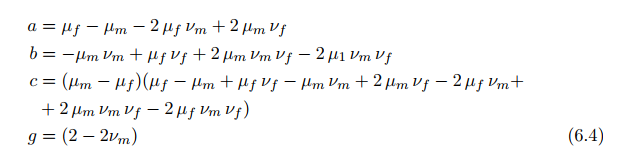


$$g=\left(2-2*\nu_m \right)$$


g=2-2*NU_m;

Constantes que dependen del volumen de fibra:


$$S_3 =0\ldotp 49247-0\ldotp 47603*V_f -0\ldotp 02748*V_f^2$$


s3=0.49247-0.47603*V_f-0.02748*((V_f)^2);


$$S_6 =0\ldotp 36844-0\ldotp 14944*V_f -0\ldotp 27152*V_f^2$$


s6=0.36844-0.14944*V_f-0.27152*((V_f)^2);


$$S_7 =0\ldotp 12346-0\ldotp 32035*V_f +0\ldotp 23517*V_f^2$$


s7=0.12346-0.32035*V_f+0.23517*((V_f)^2);

Constante D:


$$D=\frac{a*S_3^2 }{2*\mu_m^2 *c}-\frac{a*S_6 *S_3 }{\mu_m^2 *g*c}+\frac{a*\left(S_6^2 -S_7^2 \right)}{2*\mu_m^2 *g^2 *c}+\frac{S_3 *\left(b^2 -a^2 \right)}{2*\mu_m *c^2 }+\frac{S_6 *\left(a^2 -b^2 \right)+S_7 *\left(\mathrm{ab}+b^2 \right)}{2*\mu_m *g*c^2 }+\frac{\left(a^3 -2*b^3 -3*a*b^2 \right)}{8*c^3 }$$


D=a*(s3^2)/(2*(MU_m^2)*c)-a*s6*s3/((MU_m^2)*g*c)+a*((s6^2)-(s7^2))/(2*(MU_m^2)*(g^2)*c)+s3*((b^2)-(a^2))/(2*MU_m*(c^2))+(s6*(a^2-b^2)+s7*(a*b+b^2))/(2*MU_m*g*c^2)+(a^3-2*b^3-3*a*b^2)/(8*c^3);

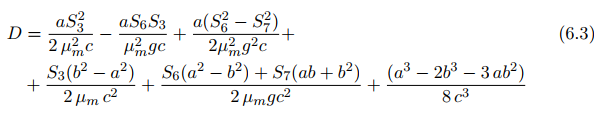

Cálculos de los coeficientes de la matriz de compliancias:


$$C_{11}^* =\lambda_m +2*\mu_m -\frac{V_f }{D}*\left\lbrack \frac{S_3^2 }{\mu_m^2 }-\frac{2*S_6 *S_3 }{\mu_m^2 *g}-\frac{a*S_3 }{\mu_m *c}+\frac{S_6^2 -S_7^2 }{\mu_m^2 *g^2 }+\frac{a*S_6 +b*S_7 }{\mu_m *g*c}+\frac{a^2 -b^2 }{4*c^2 }\right\rbrack$$


C11=LAMDA_m+2*MU_m-(V_f/D)*((s3^2)/(MU_m^2)-(2*s6*s3)/((MU_m^2)*g)-(a*s3)/(MU_m*c)+(s6^2-s7^2)/(MU_m^2*g^2)+(a*s6+b*s7)/(MU_m*g*c)+(a^2-b^2)/(4*c^2));


$$C_{12}^* =\lambda_m +\frac{V_f *b}{D}*\left\lbrack \frac{S_3 }{2*c*\mu_m }-\frac{S_6 -S_7 }{2*c*\mu_m *g}-\frac{a+b}{4*c^2 }\right\rbrack$$


C12=LAMDA_m+(V_f*b/D)*(s3/(2*c*MU_m)-(s6-s7)/(2*c*MU_m*g)-(a+b)/(4*c^2));

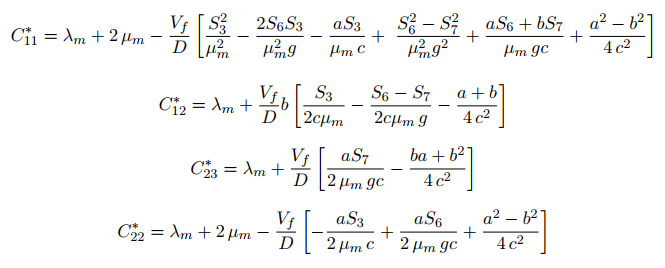


$$C_{23}^* =\lambda_m +\frac{V_f }{D}*\left\lbrack \frac{a*S_7 }{2*\mu_m *g*c}-\frac{\mathrm{ba}+b^2 }{4*c^2 }\right\rbrack$$


C23=LAMDA_m+(V_f/D)*(a*s7/(2*MU_m*g*c)-(b*a+b^2)/(4*c^2));


$$C_{22}^* =\lambda_m +2*\mu_m -\frac{V_f }{D}*\left\lbrack -\frac{a*S_3 }{2*\mu_m *c}+\frac{a*S_6 }{2*\mu_m *g*c}+\frac{a^2 -b^2 }{4*c^2 }\right\rbrack$$


C22=LAMDA_m+2*MU_m-(V_f/D)*(-a*s3/(2*MU_m*c)+a*s6/(2*MU_m*g*c)+(a^2-b^2)/(4*c^2));

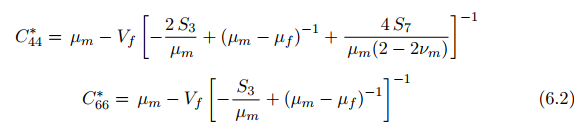


$$C_{44}^* =\mu_m -\frac{V_f }{\left\lbrack -\frac{2*S_3 }{\mu_m }+\frac{1}{\left(\mu_m -\mu_f \right)}+\frac{4*S_7 }{\mu_m *\left(2-2*\nu_m \right)}\right\rbrack }$$


C44=MU_m-V_f/(-2*s3/MU_m+1/(MU_m-MU_f)+4*s7/(MU_m*(2-2*NU_m)));


$$C_{66}^* =\mu_m -\frac{V_f }{\left\lbrack -\frac{S_3 }{\mu_m }+\frac{1}{\mu_m -\mu_f }\right\rbrack }$$


C66=MU_m-V_f/(-s3/MU_m+1/(MU_m-MU_f));

Constantes Ingenieriles:


$$E_1 =C_{11}^* -\frac{2*C_{12}^* }{C_{22}^* +C_{23}^* }$$


E1_PMM=C11-2*C12/(C22+C23);


$$E_2 =\frac{\left(2*C_{11}^* *C_{22}^* +2*C_{11}^* *C_{23}^* -4*{C_{12}^* }^2 \right)*\left(C_{22}^* -C_{23}^* +2*C_{44}^* \right)}{3*C_{11}^* *C_{22}^* +C_{11}^* *C_{23}^* +2*C_{11}^* *C_{44}^* -4*{C_{12}^* }^2 }$$


E2_PMM=(2*C11*C22+2*C11*C23-4*C12^2)*(C22-C23+2*C44)/(3*C11*C22+C11*C23+2*C11*C44-4*C12^2);


$$G_{12} =C_{66}^*$$


G12_PMM=C66;


$$G_{13} =G_{12}$$


G13_PMM=G12_PMM;


$$\nu_{12} =\frac{C_{12}^* }{C_{22}^* +C_{23}^* }$$


NU12_PMM=C12/(C22+C23);


$$\nu_{13} =\nu_{12}$$


NU13_PMM=NU12_PMM;

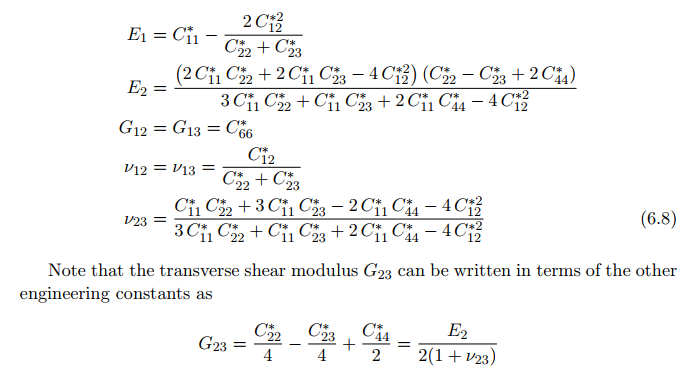


$$\nu_{23} =\frac{C_{11}^* *C_{22}^* +3*C_{11}^* *C_{23}^* -2*C_{11}^* *C_{44}^* -4*{C_{12}^* }^2 }{3*C_{11}^* *C_{22}^* +C_{11}^* *C_{23}^* +2*C_{11}^* *C_{44}^* -4*{C_{12}^* }^2 }$$


NU23_PMM=(C11*C22+3*C11*C23-2*C11*C44-4*C12^2)/(3*C11*C22+C11*C23+2*C11*C44-4*C12^2);


$$G_{23} =\frac{E_2 }{2*\left(1+\nu_{23} \right)}$$


G23_PMM=E2_PMM/(2*(1+NU23_PMM));

## Resumen de Constantes Ingenieriles:

Constantes_ingenieriles = table([E1_RM;E2_RM;G12_RM;G23_RM;NU12_RM;NU23_RM],[E1_PMM;E2_PMM;G12_PMM;G23_PMM;NU12_PMM;NU23_PMM],'VariableNames',{'RM','PMM'},'RowNames',{'E1','E2','G12','G23','NU12','NU23'})

Constantes_ingenieriles = 6×2 table
               RM         PMM  
            ________    _______

    E1        98.272     97.043
    E2        5.1555     7.7839
    G12         1.87     2.5936
    G23       2.3543     2.5545
    NU12       0.308     0.2983
    NU23    0.094891    0.52355
